# **Welcome to Deci**

**A fluid pipeline to analyze EEG Data with ease**

Written and Compiled by @John Nguyen of Robert Reinhart Lab on 10/15/2018, contact: Akida@bu.edu

## 0. MainMenu

Deci = [];
Deci.Folder.Raw         = ['C:\Users\User\Desktop\John\Newstru\Newstru2\RawData'];    
Deci.SubjectList = 'gui';  
Deci.Step               = 5;
Deci.Proceed            = false;  
Deci.PCom               = false;                           % Activates Parallel Computing (if availible)
Deci.Folder.Version     = ['C:\Users\User\Desktop\John\Newstru\Newstru2\ProcessedData'];    

## 1. Trial Definitions

    Deci.DT.Type = 'Manual';             
    Deci.DT.Starts     = {9};         %Cell Array of Markers for ETs Start.
    Deci.DT.Ends       = {10};         %Cell Array of Markers for ETs End.
    Deci.DT.Markers    = {[20 21 23 24] [27 28] [31 32] [51 52]};   
    Deci.DT.Locks      = [14 30 50];
    Deci.DT.Toi        = [-2 3]; 
    
    Deci.DT.Block.Start = {11};
    Deci.DT.Block.End = {12};
    Deci.DT.Block.Markers = [];

## 2. PreProcessing Steps

Deci.PP.Demean              = [-.5 -.2];        % [Beg End], Secs Relative to .DT.Locks, Baseline Window for Correction.

## 3. Artifact Rejection

Deci.Art.RejectNans            =true;   
Deci.Art.crittoilim = [-.5 1.5];  
Deci.Art.bpf = [1 80];

## 4. Analysis

#### General Set-Up

Deci.Analysis.Laplace            =true;                   % Leave .Laplace as 0 to not do a Laplacian Transformation based on file realistic_1005.txt format
Deci.Analysis.Locks = [1 2 3]; 
Deci.Analysis.DownSample = 500;

#### Time-Frequency Analysis

Deci.Analysis.Freq.do = false;
Deci.Analysis.Freq.method        = 'wavelet';    % Currently only uses Wavelet Decomp
Deci.Analysis.Freq.foi           = exp(linspace(log(4),log(40),20));       % Frequency of Interest
Deci.Analysis.Freq.width         = 7 ;           % Width
Deci.Analysis.Freq.gwidth        = 3;            % Gwidth
Deci.Analysis.Freq.Toi           = [-.5 1.5];       % Time Range
Deci.Analysis.Freq.Toilim        = [-2 3]; 


Deci.Analysis.Var =false;
Deci.Analysis.Clean = true;

#### ERP

Deci.Analysis.ERP.do  = true;
Deci.Analysis.ERP.Toi = [-.5 1.5];

## 5. Plotting

    Deci.Plot.Lock = '3';
    Deci.Plot.Conditions = {[20 31 51] [21 31 51] [23 31 51] [24 31 51] [20 31 52] [21 31 52] [23 31 52] [24 31 52] ...
                            [20 32 51] [21 32 51] [23 32 51] [24 32 51] [20 32 52] [21 32 52] [23 32 52] [24 32 52]};
    Deci.Plot.Var = false;
    Deci.Plot.GA = true;

#### Math

Deci.Plot.Math.Form = {'[x4+x16]/2','[x8+x12]/2'};   
%Deci.Plot.Math.Type = 0;


#### Conditions

Deci.Plot.Draw = {[1:16] [2 6] [17 18] [1 5]};
Deci.Plot.Title = {'All-trials' 'traditional-opt-10' 'non-valence-Expectation' 'traditional-opt-20'};
Deci.Plot.Subtitle = {{'G_BTE' 'g_BTE' 'Z_BTE' 'Y_BTE' 'G_WTE' 'g_WTE' 'Z_WTE' 'Y_WTE' ...
                       'N_BTE' 'n_BTE' '0_WTE' 'X_WTE' 'N_WTE' 'n_WTE' '0_BTE' 'X_BTE'} {'+RPE' '-PPE'} {'Expected' 'Unexpected'} ...
                       {'+RPE' '-PPE'}};
Deci.Plot.Figures = [false true true true];

#### Time-Frequency

%Deci.Plot.Freq.Foi = [];
Deci.Plot.Freq.Foi = [4 8];
Deci.Plot.Freq.Toi = [];
Deci.Plot.Freq.Channel = ['Reinhart-All'];
Deci.Plot.Freq.Type = 'TotalPower';     % Use 'TotalPower','ITPC' or 'EvokedPower'

Deci.Plot.Freq.Bsl = [-.5 -.2];           % Baseline Correction Time
Deci.Plot.Freq.Roi = 'maxabs';          % use 'maxmin','maxabs or [min max] to set.
Deci.Plot.Freq.BslType ='db';    % Use 'absolute','relative','relchange','db','normchange'

Deci.Plot.Freq.Topo =1;
Deci.Plot.Freq.Square =0;

Deci.Plot.Freq.Wires.avg =  'freq';

**ERP**

Deci.Plot.ERP.Toi = [0 .8];
Deci.Plot.ERP.Channel = ['Reinhart-All'];

Deci.Plot.ERP.Bsl = [-.5 -.2];           % Baseline Correction Time

Deci.Plot.ERP.Topo =1;
Deci.Plot.ERP.Wires =0;
Deci.Plot.ERP.errorbars =  true;


#### Behavioral

Deci.Plot.Behv = [];
Deci.Plot.Behv.Source = 'Definition';

Deci.Plot.Behv.Acc.Total = {[1 2 5 6 9 10 13 14] [3 7 11 15] [4 8 12 16]};
Deci.Plot.Behv.Acc.Subtotal = {[1 2 5 6] [3 7] [4 8]};
Deci.Plot.Behv.Acc.Title = {'Traditional GN' 'OZ' 'XY'};
Deci.Plot.Behv.Acc.Subtitle = {'Percent Choice Opt' 'Percent 0' 'Percent X'};

Deci.Plot.Behv.Acc.Block = [1:6];
Deci.Plot.Behv.Acc.Collapse.Trial =false;
Deci.Plot.Behv.Acc.Collapse.Block = true;
Deci.Plot.Behv.Acc.Collapse.Subject = false;
Deci.Plot.Behv.Acc.Collapse.Uneven = 'maxlength:nans';
Deci.Plot.Behv.Acc.Collapse.Movmean =  true;

Deci.Plot.Behv.RT.Draw = {[1 2 5 6] [9 10 13 14] [3 7] [11 15] [4 8] [12 16]};
Deci.Plot.Behv.RT.Title = {'Gg RT' 'Nn RT' '0 RT' 'X RT' 'Z RT' 'Y RT'};
Deci.Plot.Behv.RT.Subtitle = {'Gg RT' 'Nn RT' '0 RT' 'X RT' 'Z RT' 'Y RT'};
Deci.Plot.Behv.RT.Locks = [1 2];

Deci.Plot.Behv.RT.Block = [1:6];
Deci.Plot.Behv.RT.Collapse.Trial =false;
Deci.Plot.Behv.RT.Collapse.Block = true;
Deci.Plot.Behv.RT.Collapse.Subject = false;
Deci.Plot.Behv.RT.Collapse.Uneven = 'maxlength:nans';

Options

Deci.Run.Behavior = false;
Deci.Run.Freq =true;
Deci.Run.ERP =false;
Deci.Run.CFC = false;

## ** 6. Run**

Channel AF3 of 60
Channel AF4 of 60
Channel AF7 of 60
Channel AF8 of 60
Channel AFz of 60
Channel C1 of 60
Channel C2 of 60
Channel C3 of 60
Channel C4 of 60
Channel C5 of 60
Channel C6 of 60
Channel CP1 of 60
Channel CP2 of 60
Channel CP3 of 60
Channel CP4 of 60
Channel CP5 of 60
Channel CP6 of 60
Channel CPz of 60
Channel Cz of 60
Channel F1 of 60
Channel F2 of 60
Channel F3 of 60
Channel F4 of 60
Channel F5 of 60
Channel F6 of 60
Channel F7 of 60
Channel F8 of 60
Channel FC1 of 60
Channel FC2 of 60
Channel FC3 of 60
Channel FC4 of 60
Channel FC5 of 60
Channel FC6 of 60
Channel FCz of 60
Channel FT7 of 60
Channel FT8 of 60
Channel Fz of 60
Channel O1 of 60
Channel O2 of 60
Channel Oz of 60
Channel P1 of 60
Channel P2 of 60
Channel P3 of 60
Channel P4 of 60
Channel P5 of 60
Channel P6 of 60
Channel P7 of 60
Channel P8 of 60
Channel PO3 of 60
Channel PO4 of 60
Channel PO7 of 60
Channel PO8 of 60
Channel POz of 60
Channel Pz of 60
Channel T7 of 60
Channel T8 of 60
Channel TP10 of 60
Cha

preprocessing
preprocessing trial 374 from 374

the call to "ft_preprocessing" took 38 seconds
the input is raw data with 60 channels and 374 trials
averaging trials
averaging trial 73 of 73

the call to "ft_timelockanalysis" took 0 seconds
the input is timelock data with 60 channels and 801 timebins
applying baseline correction on avg
baseline correction invalidates previous variance estimate, removing var
the call to "ft_timelockbaseline" took 0 seconds
the input is raw data with 60 channels and 374 trials
averaging trials
averaging trial 59 of 59

the call to "ft_timelockanalysis" took 0 seconds
the input is timelock data with 60 channels and 801 timebins
applying baseline correction on avg
baseline correction invalidates previous variance estimate, removing var
the call to "ft_timelockbaseline" took 0 seconds
the input is raw data with 60 channels and 374 trials
averaging trials
averaging trial 24 of 24

the call to "ft_timelockanalysis" took 0 seconds
the input is timelock data wi

preprocessing
preprocessing trial 399 from 399

the call to "ft_preprocessing" took 41 seconds
the input is raw data with 60 channels and 399 trials
averaging trials
averaging trial 63 of 63

the call to "ft_timelockanalysis" took 0 seconds
the input is timelock data with 60 channels and 801 timebins
applying baseline correction on avg
baseline correction invalidates previous variance estimate, removing var
the call to "ft_timelockbaseline" took 0 seconds
the input is raw data with 60 channels and 399 trials
averaging trials
averaging trial 70 of 70

the call to "ft_timelockanalysis" took 0 seconds
the input is timelock data with 60 channels and 801 timebins
applying baseline correction on avg
baseline correction invalidates previous variance estimate, removing var
the call to "ft_timelockbaseline" took 0 seconds
the input is raw data with 60 channels and 399 trials
averaging trials
averaging trial 29 of 29

the call to "ft_timelockanalysis" took 0 seconds
the input is timelock data wi

preprocessing
preprocessing trial 382 from 382

the call to "ft_preprocessing" took 39 seconds
the input is raw data with 60 channels and 382 trials
averaging trials
averaging trial 76 of 76

the call to "ft_timelockanalysis" took 0 seconds
the input is timelock data with 60 channels and 801 timebins
applying baseline correction on avg
baseline correction invalidates previous variance estimate, removing var
the call to "ft_timelockbaseline" took 0 seconds
the input is raw data with 60 channels and 382 trials
averaging trials
averaging trial 68 of 68

the call to "ft_timelockanalysis" took 0 seconds
the input is timelock data with 60 channels and 801 timebins
applying baseline correction on avg
baseline correction invalidates previous variance estimate, removing var
the call to "ft_timelockbaseline" took 0 seconds
the input is raw data with 60 channels and 382 trials
averaging trials
averaging trial 16 of 16

the call to "ft_timelockanalysis" took 0 seconds
the input is timelock data wi

preprocessing
preprocessing trial 411 from 411

the call to "ft_preprocessing" took 41 seconds
the input is raw data with 60 channels and 411 trials
averaging trials
averaging trial 81 of 81

the call to "ft_timelockanalysis" took 0 seconds
the input is timelock data with 60 channels and 801 timebins
applying baseline correction on avg
baseline correction invalidates previous variance estimate, removing var
the call to "ft_timelockbaseline" took 0 seconds
the input is raw data with 60 channels and 411 trials
averaging trials
averaging trial 77 of 77

the call to "ft_timelockanalysis" took 0 seconds
the input is timelock data with 60 channels and 801 timebins
applying baseline correction on avg
baseline correction invalidates previous variance estimate, removing var
the call to "ft_timelockbaseline" took 0 seconds
the input is raw data with 60 channels and 411 trials
averaging trials
averaging trial 26 of 26

the call to "ft_timelockanalysis" took 0 seconds
the input is timelock data wi

preprocessing
preprocessing trial 372 from 372

the call to "ft_preprocessing" took 37 seconds
the input is raw data with 60 channels and 372 trials
averaging trials
averaging trial 61 of 61

the call to "ft_timelockanalysis" took 0 seconds
the input is timelock data with 60 channels and 801 timebins
applying baseline correction on avg
baseline correction invalidates previous variance estimate, removing var
the call to "ft_timelockbaseline" took 0 seconds
the input is raw data with 60 channels and 372 trials
averaging trials
averaging trial 63 of 63

the call to "ft_timelockanalysis" took 0 seconds
the input is timelock data with 60 channels and 801 timebins
applying baseline correction on avg
baseline correction invalidates previous variance estimate, removing var
the call to "ft_timelockbaseline" took 0 seconds
the input is raw data with 60 channels and 372 trials
averaging trials
averaging trial 40 of 40

the call to "ft_timelockanalysis" took 0 seconds
the input is timelock data wi

preprocessing
preprocessing trial 383 from 383

the call to "ft_preprocessing" took 39 seconds
the input is raw data with 60 channels and 383 trials
averaging trials
averaging trial 56 of 56

the call to "ft_timelockanalysis" took 0 seconds
the input is timelock data with 60 channels and 801 timebins
applying baseline correction on avg
baseline correction invalidates previous variance estimate, removing var
the call to "ft_timelockbaseline" took 0 seconds
the input is raw data with 60 channels and 383 trials
averaging trials
averaging trial 48 of 48

the call to "ft_timelockanalysis" took 0 seconds
the input is timelock data with 60 channels and 801 timebins
applying baseline correction on avg
baseline correction invalidates previous variance estimate, removing var
the call to "ft_timelockbaseline" took 0 seconds
the input is raw data with 60 channels and 383 trials
averaging trials
averaging trial 42 of 42

the call to "ft_timelockanalysis" took 0 seconds
the input is timelock data wi

preprocessing
preprocessing trial 369 from 369

the call to "ft_preprocessing" took 37 seconds
the input is raw data with 60 channels and 369 trials
averaging trials
averaging trial 69 of 69

the call to "ft_timelockanalysis" took 0 seconds
the input is timelock data with 60 channels and 801 timebins
applying baseline correction on avg
baseline correction invalidates previous variance estimate, removing var
the call to "ft_timelockbaseline" took 0 seconds
the input is raw data with 60 channels and 369 trials
averaging trials
averaging trial 52 of 52

the call to "ft_timelockanalysis" took 0 seconds
the input is timelock data with 60 channels and 801 timebins
applying baseline correction on avg
baseline correction invalidates previous variance estimate, removing var
the call to "ft_timelockbaseline" took 0 seconds
the input is raw data with 60 channels and 369 trials
averaging trials
averaging trial 36 of 36

the call to "ft_timelockanalysis" took 0 seconds
the input is timelock data wi

preprocessing
preprocessing trial 387 from 387

the call to "ft_preprocessing" took 39 seconds
the input is raw data with 60 channels and 387 trials
averaging trials
averaging trial 78 of 78

the call to "ft_timelockanalysis" took 0 seconds
the input is timelock data with 60 channels and 801 timebins
applying baseline correction on avg
baseline correction invalidates previous variance estimate, removing var
the call to "ft_timelockbaseline" took 0 seconds
the input is raw data with 60 channels and 387 trials
averaging trials
averaging trial 72 of 72

the call to "ft_timelockanalysis" took 0 seconds
the input is timelock data with 60 channels and 801 timebins
applying baseline correction on avg
baseline correction invalidates previous variance estimate, removing var
the call to "ft_timelockbaseline" took 0 seconds
the input is raw data with 60 channels and 387 trials
averaging trials
averaging trial 50 of 50

the call to "ft_timelockanalysis" took 0 seconds
the input is timelock data wi

preprocessing
preprocessing trial 383 from 383

the call to "ft_preprocessing" took 39 seconds
the input is raw data with 60 channels and 383 trials
averaging trials
averaging trial 75 of 75

the call to "ft_timelockanalysis" took 0 seconds
the input is timelock data with 60 channels and 801 timebins
applying baseline correction on avg
baseline correction invalidates previous variance estimate, removing var
the call to "ft_timelockbaseline" took 0 seconds
the input is raw data with 60 channels and 383 trials
averaging trials
averaging trial 70 of 70

the call to "ft_timelockanalysis" took 0 seconds
the input is timelock data with 60 channels and 801 timebins
applying baseline correction on avg
baseline correction invalidates previous variance estimate, removing var
the call to "ft_timelockbaseline" took 0 seconds
the input is raw data with 60 channels and 383 trials
averaging trials
averaging trial 42 of 42

the call to "ft_timelockanalysis" took 0 seconds
the input is timelock data wi

the call to "ft_timelockgrandaverage" took 0 seconds
computing average of avg over 9 subjects


the call to "ft_timelockgrandaverage" took 0 seconds
computing average of avg over 9 subjects


the call to "ft_timelockgrandaverage" took 0 seconds
computing average of avg over 9 subjects


the call to "ft_timelockgrandaverage" took 0 seconds
computing average of avg over 9 subjects


the call to "ft_timelockgrandaverage" took 0 seconds
computing average of avg over 9 subjects


the call to "ft_timelockgrandaverage" took 0 seconds
computing average of avg over 9 subjects


the call to "ft_timelockgrandaverage" took 0 seconds
computing average of avg over 9 subjects


the call to "ft_timelockgrandaverage" took 0 seconds
computing average of avg over 9 subjects


the call to "ft_timelockgrandaverage" took 0 seconds
computing average of avg over 9 subjects


the call to "ft_timelockgrandaverage" took 0 seconds
computing average of avg over 9 subjects


the call to "ft_timelockgrandaverage" took 0 seconds
computing average of avg over 9 subjects


the call to "ft_timelockgrandaverage" took 0 seconds
computing average of avg over 9 subjects


the call to "ft_timelockgrandaverage" took 0 seconds
computing average of avg over 9 subjects


the call to "ft_timelockgrandaverage" took 0 seconds
computing average of avg over 9 subjects


the call to "ft_timelockgrandaverage" took 0 seconds
computing average of avg over 9 subjects


the call to "ft_timelockgrandaverage" took 0 seconds
computing average of avg over 9 subjects


the call to "ft_timelockgrandaverage" took 0 seconds
computing average of avg over 9 subjects


the call to "ft_timelockgrandaverage" took 0 seconds
computing average of avg over 9 subjects


the call to "ft_timelockgrandaverage" took 0 seconds
computing average of avg over 9 subjects


the call to "ft_timelockgrandaverage" took 0 seconds
computing average of avg over 9 subjects


the call to "ft_timelockgrandaverage" took 0 seconds
computing average of avg over 9 subjects


the call to "ft_timelockgrandaverage" took 0 seconds
computing average of avg over 9 subjects


the call to "ft_timelockgrandaverage" took 0 seconds
computing average of avg over 9 subjects


the call to "ft_timelockgrandaverage" took 0 seconds
computing average of avg over 9 subjects


the call to "ft_timelockgrandaverage" took 0 seconds
computing average of avg over 9 subjects


the call to "ft_timelockgrandaverage" took 0 seconds
computing average of avg over 9 subjects


the call to "ft_timelockgrandaverage" took 0 seconds
computing average of avg over 9 subjects


the call to "ft_timelockgrandaverage" took 0 seconds
computing average of avg over 9 subjects


the call to "ft_timelockgrandaverage" took 0 seconds
computing average of avg over 9 subjects


the call to "ft_timelockgrandaverage" took 0 seconds
computing average of avg over 9 subjects


the call to "ft_timelockgrandaverage" took 0 seconds
computing average of avg over 9 subjects


the call to "ft_timelockgrandaverage" took 0 seconds
computing average of avg over 9 subjects


the call to "ft_timelockgrandaverage" took 0 seconds
computing average of avg over 9 subjects


the call to "ft_timelockgrandaverage" took 0 seconds
computing average of avg over 9 subjects


the call to "ft_timelockgrandaverage" took 0 seconds
computing average of avg over 9 subjects


the call to "ft_timelockgrandaverage" took 0 seconds


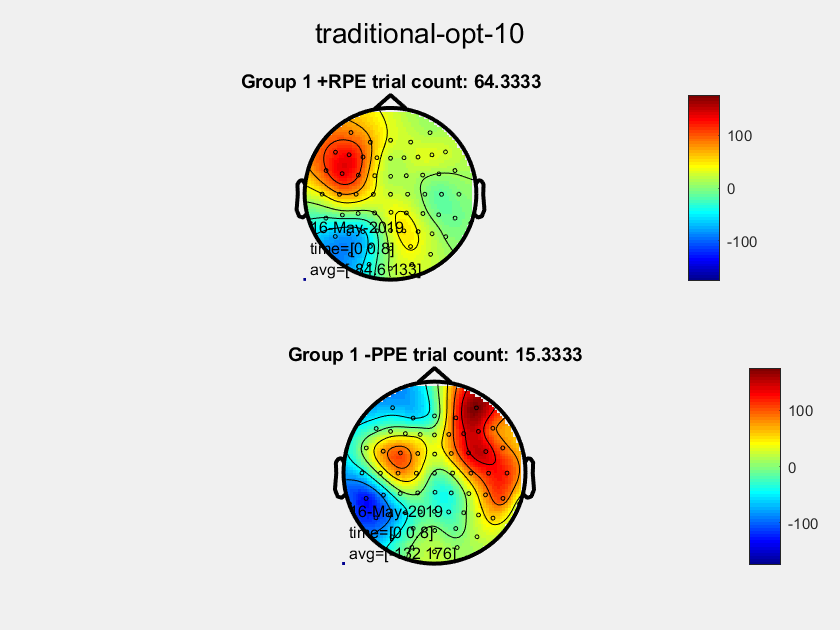

reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 1 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


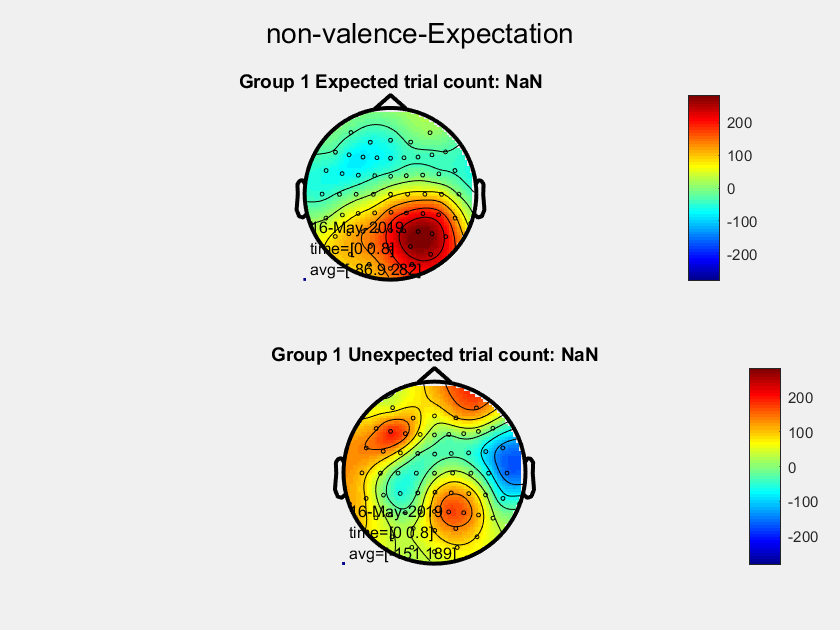

reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds


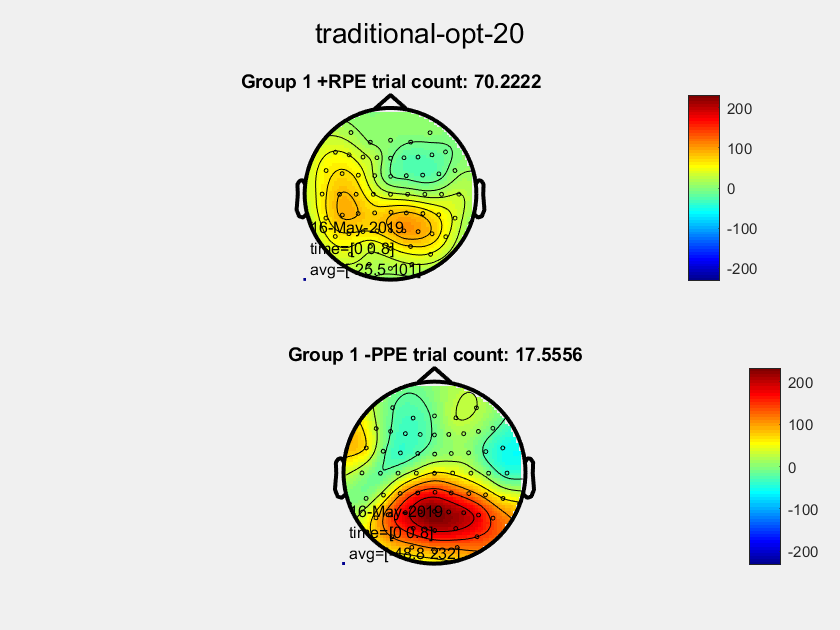

reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds
reading layout from file easycap_rob_binocular.mat
the call to "ft_prepare_layout" took 0 seconds
the call to "ft_topoplotER" took 0 seconds



Deci_Backend(Deci);